clear 
close all
clc
syms x;

Wrocław 20.06.2021

Aleksander Kudyba   

245084

# Numeryczne rozwiązanie równania Poissona dla złącza Schottky’ego.

Dla wyznaczenia parametrów złącza metal - półprzewodnik rozwiązano równanie Poisson'a numerycznie, odwrotną metodą Eulera. Postać rozwiązywanego równania była następująca:


$$\frac{dV^2}{dx^2}=-\frac{qN_d\left(1-exp\left(\frac{eV(x)}{kT}\right)\right)}{\varepsilon_0 \varepsilon_r}
$$


Które zostaje rozbite na dwa równania dla gradientu pola elektrycznego i potencjału,

$\rho(x)=qN_d\left(1-exp\left(\frac{eV(x)}{kT}\right)\right)$ - gęstość ładunku wyliczana na podstawie warunków początkowych.


$$\frac{dE(x)}{dx} = \frac{\rho(x)}{\varepsilon_0 \varepsilon_r}
$$



$$\frac{dV(x)}{dx} = -E(x)$$


T = 300;
W_gold = 5.1;
Si_aff = 4.05;

kB1 = 1.380649e-23; %J/K
kB2 = 8.617*1e-5; %eV*K
q = 1.602e-19; %C
eps_Si = 11.7; %F/m 
eps = eps_Si * 8.85417e-12; %F/m


Eg(x) = 1.17-4.73*1e-4*x^2/(x+636); %energy centered e.g. equal to zero at Ei
E_g = double(Eg(T));
E_c = E_g/2;
Nc(x) = 6.2*1e15*x^(3/2);
N_c = double(Nc(T));
Nv(x) = 3.5*1e15*x^(3/2);
N_v = double(Nv(T));
ni(x) = (N_c*N_v)^(1/2)*exp(-E_g/2/kB2/x);
n_i = double(ni(T));

Podaj wartość koncentracji domieszek:

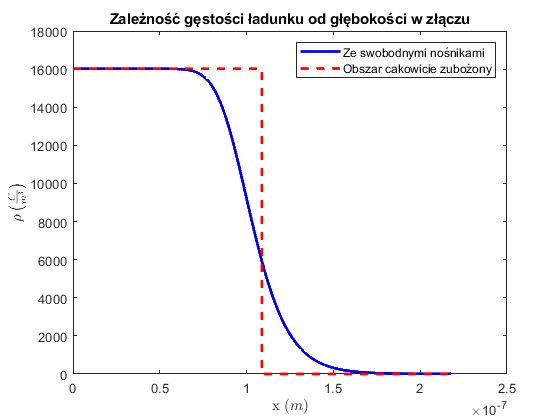

Nd_temp = "1e17"; %n-type doped silicon
Nd_cm = str2double(Nd_temp); %cm^-3
Nd = Nd_cm.*1e6; %m^-3
Ld = sqrt((eps*kB1*300)/(q^2*Nd)); %m
Ld_micro = Ld*1e6;
Ef_shift = kB2*T*log(Nd_cm/n_i); 
psiB = W_gold - Si_aff;
Nv = 3.5*1e15*T^(3/2);
%Vbi zmień na wartość dla przybliżenia całkowicie zubożonego obszaru
Vbi = psiB - kB2*T*log(N_v/Nd_cm);
xd = sqrt((2*eps*(Vbi)/(q*Nd))); %m
xd_micro = xd*1e6;
Vend = -((kB2*300))*exp(-xd/Ld); %V
%q.*Nd*(1-exp((q*Vend)/(kB1*300)))

dt = xd/1e3;
t0 = 2*xd;
tf = 0;

t = 0:dt:t0;
rho = zeros(size(t));
E = zeros(size(t));
V = zeros(size(t));
rho(end)= 0;
E(end) = 0;
V(end) = Vend;
i = length(t) - 1;

%swobodne nośniki w obszrze zubożonym
for j=1:1:length(t)-1
    rho(i) = q.*Nd*(1-exp((V(i+1))/(kB2*300)));  %forward 
    E(i) = E(i+1) - dt*(rho(i)/eps);
    V(i) = V(i+1) + dt*E(i);
    i = i - 1;
    %y(i+1) = fzero(@(Y) y(i) - dt*Y - Y,y(i), options); %backward
    %ye(i+1) = exp(t(i+1)); %exact
end

% for j=1:1:length(t)-1
%     rho(i) = q.*Nd %forward 
%     E(i) = E(i+1) - dt*(rho(i)/eps);
%     V(i) = V(i+1) + dt*E(i);
%     i = i - 1;
%     %y(i+1) = fzero(@(Y) y(i) - dt*Y - Y,y(i), options); %backward
%     %ye(i+1) = exp(t(i+1)); %exact
% end

s1 = linspace(0,xd,1e3);
s2 = linspace(xd,t(end),1e3);

empty = zeros(1,length(s1));
empty = zeros(1,length(s2));
empty_V = zeros(1,length(s1));
rho_d_area = q*Nd * ones(1, length(s1));
E_d_area = -(q*Nd/eps)*(xd-s1);
V_d_area = ((q*Nd/2/eps)*(xd-s1).^2);


plot(t, rho, 'b-', 'LineWidth', 2)
hold on 
plot([s1  s2], [rho_d_area   empty], 'r--','LineWidth', 2)
hold off
xlabel("x $(m)$",'Interpreter','latex');
ylabel(" $\rho \left(\frac{C}{m^3}\right)$",'Interpreter','latex');
legend("Ze swobodnymi nośnikami", "Obszar cakowicie zubożony")
title("Zależność gęstości ładunku od głębokości w złączu")

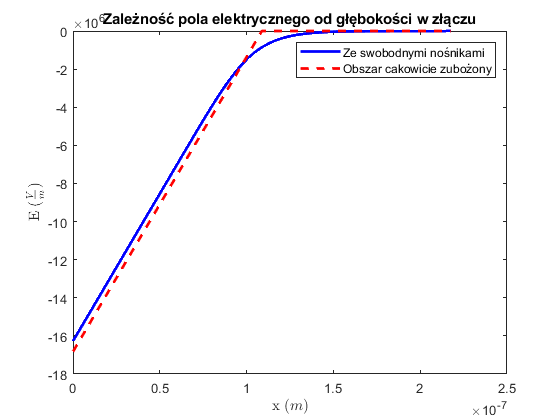


plot(t, E, 'b-','LineWidth', 2)
hold on 
plot([s1 s2],[E_d_area empty], 'r--','LineWidth', 2)
hold off
xlabel("x $(m)$",'Interpreter','latex');
ylabel("E $(\frac{V}{m})$",'Interpreter','latex');
legend("Ze swobodnymi nośnikami", "Obszar cakowicie zubożony")
title("Zależność pola elektrycznego od głębokości w złączu")

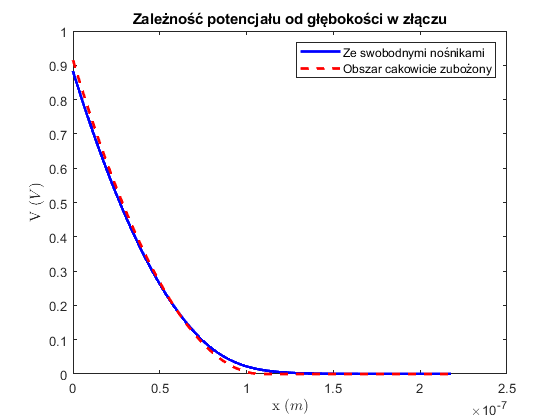


plot(t, -V, 'b-', 'LineWidth', 2)
hold on 
plot([s1 s2], [V_d_area empty_V], 'r--','LineWidth', 2)
hold off
xlabel("x $(m)$",'Interpreter','latex');
ylabel("V $(V)$",'Interpreter','latex');
legend("Ze swobodnymi nośnikami", "Obszar cakowicie zubożony")
title("Zależność potencjału od głębokości w złączu")